Let's start by importing the data andseparating the input and output variables.

data = importdata('doe_results.csv',',',7)

data = struct with fields:
        data: [201×22 double]
    textdata: {208×23 cell}


X = data.data(:,[1 2]);     % Inputs
Y = data.data(:,6:end);     % Outputs

Now let's generate the Response Variable, which is the max temp difference accross the entire array.

for i = 1:size(X,1)
    maxDiff(i,:) = computeMaxTempDiff(Y(i,:));
end

tempMse = sum((Y - mean(Y,2)).^2,2)/size(Y,1);

Now let's fit a Gaussian Process Regression with the unscaled data.

mdl = fitrgp([X(:,1),X(:,2)],maxDiff);

Let's create the values for the response surface

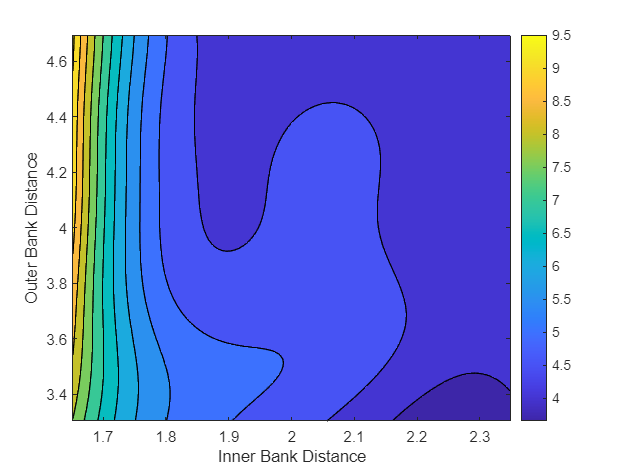

x1 = min(X(:,1)):(max(X(:,1))-min(X(:,1)))/100:max(X(:,1));
x2 = min(X(:,2)):(max(X(:,2))-min(X(:,2)))/100:max(X(:,2));
[X1,X2] = meshgrid(x1,x2);
for i = 1:size(X1,1)
    Ypred(:,i) = mdl.predict([X1(:,i),X2(:,i)]);
end

contourf(X1,X2,Ypred); colorbar; xlabel('Inner Bank Distance'); ylabel('Outer Bank Distance');

Let's plot the data along with the response surface

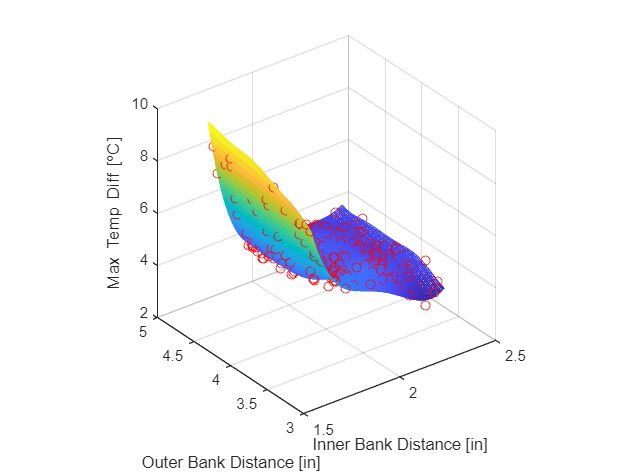

plot3(X(:,1),X(:,2),maxDiff,'or');  % Plot the data
grid on; axis square;
xlabel('Inner Bank Distance [in]');
ylabel('Outer Bank Distance [in]');
zlabel('Max Temp Diff [^oC]');
hold on; mesh(X1,X2,Ypred);         % Plot the response surface

Let's create an anonymus function for the model'sm predict utility and use it as our objective function during the optimization routine.

fun = @(x)mdl.predict(x);

fun([2 4])      % Test that the function call works

ans = 4.5816

Call the Genetic Algorithm optimizer

[x_final,fval] = ga(fun,2,[],[],[],[],min([X(:,1),X(:,2)]),max([X(:,1),X(:,2)]))

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x_final =     2.2771    3.3040


fval = 3.6591

The optimizer predicts that the best possible configuration has the inner bank with a distance of 2.2771 in away from the center, and the outer at 3.3040 in, which should minimize the max temp difference to 3.6591 C. We take those distance values and input them back into ANSYS to see how much the results from the CFD model differ from the GRP prediction. The values we get back from the CFD model with the optimized configuration are:

final = [327.73466	325.74192	328.45215	327.91047	327.37785	327.67879	324.82095,...
    325.62783	326.14916	325.7202	327.07958	326.2581	326.42718	326.3839	324.85325	325.32756	326.21105];

Let's call the response variable function to compute the max temp difference for these results.

computeMaxTempDiff(final)

ans = 3.6312

Below is an auxiliary function to compute the response variable.

function maxDiff = computeMaxTempDiff(Y)
        maxDiff = max(max(abs(triu(Y.*...
        ones(length(Y),length(Y)) -...
        Y'.*ones(length(Y),length(Y))))));
end